## Solar System Simulator

% Input Gregorian date
year = 2023;
month = 8;
day = 27;
hr = 12;
min = 0;
sec = 0;

% Input number of years your want to simulate
tn = 5; % in (year)

% Converting Gergorian date in Julian Date
JD = UTC2JD(2023, 8, 27, 12, 0, 0)

JD = 2460184


% Calculating number of Julian centuries between J2000 and input date
T0 = (JD - 2451545) / 36525

T0 = 0.2365


% Constants
G = 6.6743e-20;     % Universal Gravitational Constant
mS = 1.989e30;      % Mass of Sun
mMc = 330.2e21;     % Mass of Mercury
mV = 4.869e24;      % Mass of Venus
mE = 5.972e24;      % Mass of Earth
mM = 641.9e21;      % Mass of Mars
mJ = 1.899e27;      % Mass of Jupiter
mSa = 568.5e24;     % Mass of Saturn
mU = 86.83e24;      % Mass of Uranus
mN = 102.4e24;      % Mass of Neptune

% Total mass
m = mS + mMc + mV + mE + mM + mJ + mSa + mU + mN;

% Declaring initial state vectors of Sun
rS = [0 0 0];
vS = [0 0 0];
% X1 = rS(1); Y1 = rS(2); Z1 = rS(3);

% Calculating initial state vectors of planets on the particular Julian date.
PlanetStates = PlanetStateVec(T0);

rMc = PlanetStates(1:3);
vMc = PlanetStates(4:6);
rV = PlanetStates(7:9);
vV = PlanetStates(10:12);
rE = PlanetStates(13:15);
vE = PlanetStates(16:18);
rM = PlanetStates(19:21);
vM = PlanetStates(22:24);
rJ = PlanetStates(25:27);
vJ = PlanetStates(28:30);
rSa = PlanetStates(31:33);
vSa = PlanetStates(34:36);
rU = PlanetStates(37:39);
vU = PlanetStates(40:42);
rN = PlanetStates(43:45);
vN = PlanetStates(46:48);

% Declaring time steps
t0 = 0; tf = tn * 365 * 24 * 60 * 60;

% Declaring initial condition
y0 = [rS(1) rS(2) rMc(1) rMc(2) rV(1) rV(2) rE(1) rE(2) rM(1) rM(2)...
      rJ(1) rJ(2) rSa(1) rSa(2) rU(1) rU(2) rN(1) rN(2)...
      vS(1) vS(2) vMc(1) vMc(2) vV(1) vV(2) vE(1) vE(2) vM(1) vM(2)...
      vJ(1) vJ(2) vSa(1) vSa(2) vU(1) vU(2) vN(1) vN(2)];

% Solving numerical integral using RK4
[t, y] = ode45(@rates, [t0 tf], y0);

% Saving results of each planet and Sun
XS  = y(:, 1); YS = y(:, 2);
XMc = y(:, 3); YMc = y(:, 4);
XV = y(:, 5); YV = y(:, 6);
XE  = y(:, 7); YE = y(:, 8);
XM  = y(:, 9); YM = y(:, 10);
XJ  = y(:, 11); YJ = y(:, 12);
XSa  = y(:, 13); YSa = y(:, 14);
XU  = y(:, 15); YU = y(:, 16);
XN  = y(:, 17); YN = y(:, 18);

% Calculating center of gravity of each body
XG = []; YG = [];
for i = 1:length(t)
    XG = [XG; (mS * XS(i)) + (mMc * XMc(i)) + (mV * XV(i)) + (mE * XE(i)) + (mM * XM(i)) + (mJ * XJ(i)) + (mSa * XSa(i)) + (mU * XU(i)) + (mN * XN(i)) / m];
    YG = [YG; (mS * YS(i)) + (mMc * YMc(i)) + (mV * YV(i)) + (mE * YE(i)) + (mM * YM(i)) + (mJ * YJ(i)) + (mSa * YSa(i)) + (mU * YU(i)) + (mN * YN(i))/ m];
end

% Saving results of center of gravity of each body
XSG = XS - XG; YSG = YS - YG; 
XMcG = XMc - XG; YMcG = YMc - YG;
XVG = XV - XG; YVG = YV - YG;
XEG = XE - XG; YEG = YE - YG;
XMG = XM - XG; YMG = YM - YG;
XJG = XJ - XG; YJG = YJ - YG;
XSaG = XSa - XG; YSaG = YSa - YG;
XUG = XU - XG; YUG = YU - YG;
XNG = XN - XG; YNG = YN - YG;

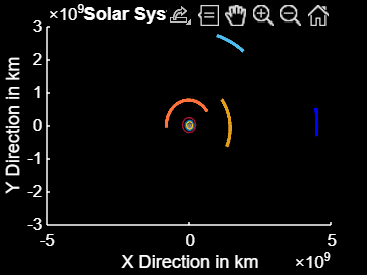

% Plotting the results 
figure('Color', 'black')
hold on;

plot(XS, YS, 'r');
plot(XMc, YMc, 'color', [.5 .5 .5]);
plot(XV, YV, 'color', '#F9C21A');
plot(XE, YE, 'color', [0 0.4470 0.7410]);
plot(XM, YM, 'color', [0.6350 0.0780 0.1840]);
plot(XJ, YJ, 'color', '#FF723A', 'LineWidth', 2);
plot(XSa, YSa, 'color', '#E39E1C', 'LineWidth', 2);
plot(XU, YU, 'color', [0.3010 0.7450 0.9330], 'LineWidth', 2);
plot(XN, YN, 'b', 'LineWidth', 2);

% Get the current axes and set their background color to black
ax = gca;
ax.Color = 'black';

% Set the text color to white for better visibility
set(ax, 'XColor', 'white', 'YColor', 'white', 'GridColor', 'white');

%view(3);  % Set 3D view
xlim([-5e9, 5e9])
ylim([-3e9, 3e9])

xlabel('X Direction in km')
ylabel('Y Direction in km')
title('Solar System Simulation', 'Color','white')

hold off;

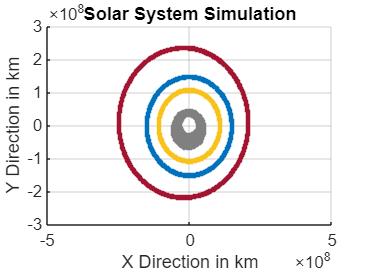

% Time step for animation
dt = 1;

% Create a figure
figure;

for t = 1:size(XS, 1)
    hold on;

    % Plot planet positions for the current time step
    plot(XMc(t, :), YMc(t, :), 'o', 'MarkerSize', 2, 'MarkerFaceColor', [.5 .5 .5], 'MarkerEdgeColor', [.5 .5 .5]);
    plot(XV(t, :), YV(t, :), 'o', 'MarkerSize', 2, 'MarkerFaceColor', '#F9C21A', 'MarkerEdgeColor', '#F9C21A');
    plot(XE(t, :), YE(t, :), 'o', 'MarkerSize', 2, 'MarkerFaceColor', [0 0.4470 0.7410], 'MarkerEdgeColor', [0 0.4470 0.7410]);
    plot(XM(t, :), YM(t, :), 'o', 'MarkerSize', 2, 'MarkerFaceColor', [0.6350 0.0780 0.1840], 'MarkerEdgeColor', [0.6350 0.0780 0.1840]);
    plot(XJ(t, :), YJ(t, :), 'o', 'MarkerSize', 3, 'MarkerFaceColor', '#FF723A', 'MarkerEdgeColor', '#FF723A');
    plot(XSa(t, :), YSa(t, :), 'o', 'MarkerSize', 3, 'MarkerFaceColor', '#E39E1C', 'MarkerEdgeColor', '#E39E1C');
    plot(XU(t, :), YU(t, :), 'o', 'MarkerSize', 3, 'MarkerFaceColor', [0.3010 0.7450 0.9330], 'MarkerEdgeColor', [0.3010 0.7450 0.9330]);
    plot(XN(t, :), YN(t, :), 'o', 'MarkerSize', 3, 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');

    %view(3);
    %text(0,0,'Sun', 'FontSize',0.5,'Color','#FF723A')
    grid on;
    hold off;

    xlim([-5e8, 5e8])
    ylim([-3e8, 3e8])
    
    xlabel('X Direction in km')
    ylabel('Y Direction in km')
    title('Solar System Simulation')

    % Draw the updated figure immediately
    drawnow;

    % Pause for a short duration to create animation effect
    pause(dt);
end